# LEXI Image Reconstruction

Without binning?

data2=restore_idl('G:\My Drive\Research\Projects\Collaborations\Hyunju Connor\LEXI_2.0','verbose');

G:\My Drive\Research\Projects\Collaborations\Hyunju Connor\LEXI_2.0
SIGNATURE = SR
----- Analysis of file structure: -----
Offset 4: record type TIMESTAMP
Offset 1100: record type VERSION
Offset 1156: record type VARIABLE
Offset 2860: record type VARIABLE
Offset 4568: record type VARIABLE
Offset 647876: record type VARIABLE
Offset 1291184: record type END_MARKER
----------
TIMESTAMP:  date, user, host =  Mon Apr 11 12:39:22 2022  Kim   DESKTOP-TN35FII 
VERSION: arch, os, release = x86_64  Win32   8.8.0   
AZM:  single  ARRAY: 401    1
THETA:  single  ARRAY: 401    1
COUNT1:  single  ARRAY: 401  401
COUNT2:  single  ARRAY: 401  401
END
Restoring AZM...
Restoring THETA...
Restoring COUNT1...
Restoring COUNT2...


% data4=restore_idl('G:\My Drive\Research\Projects\Collaborations\Hyunju Connor\LEXI_4.0');

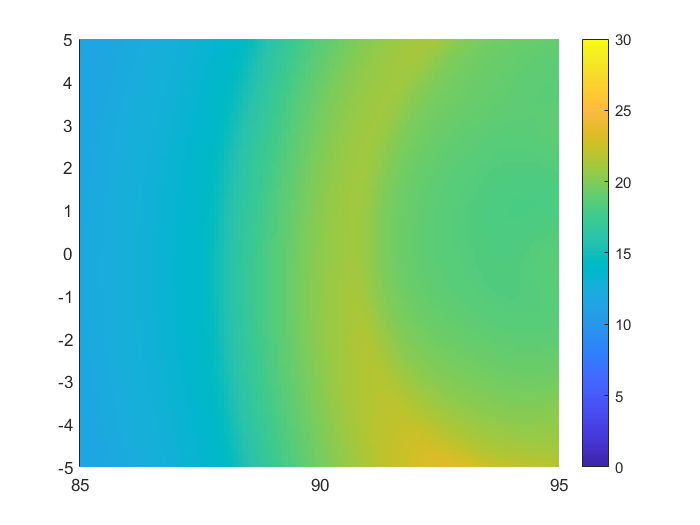

figure;
surf(data2.AZM,data2.THETA,data2.COUNT1'.*20,'EdgeColor','none');
view([0,90]);
colorbar;
caxis([0,30]);
xlim([85,95]);
ylim([-5,+5]);

test=data2.COUNT1'.*300;

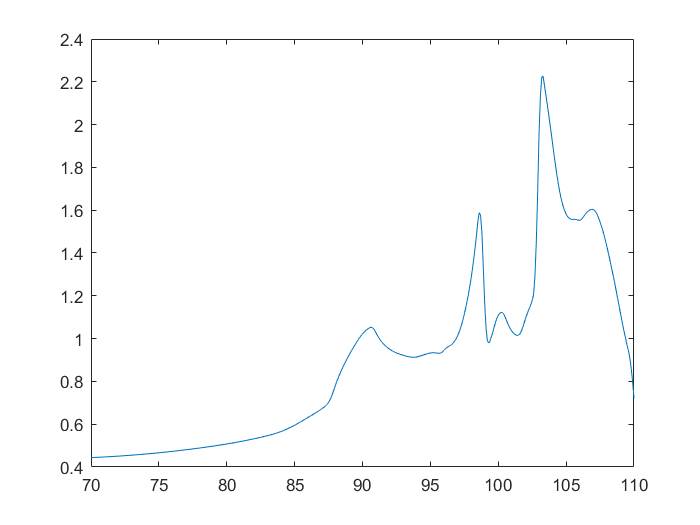

figure;

plot(data2.AZM,data2.COUNT1(:,200));

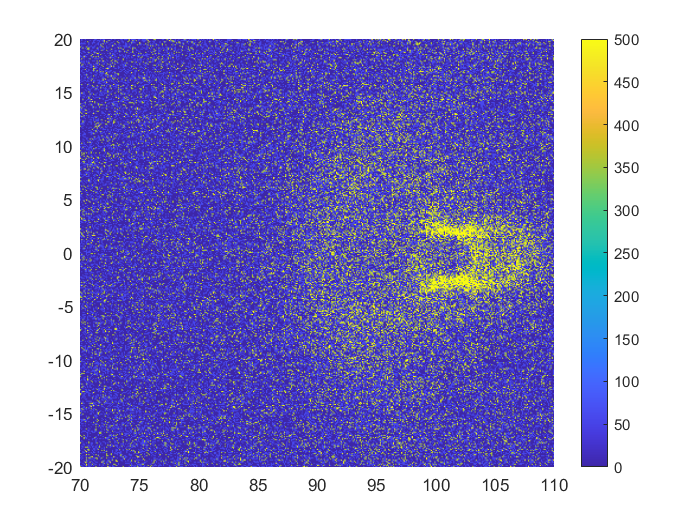

figure;
surf(data2.AZM,data2.THETA,data2.COUNT2'.*300,'EdgeColor','none');
view([0,90]);
colorbar;
caxis([0,500]);

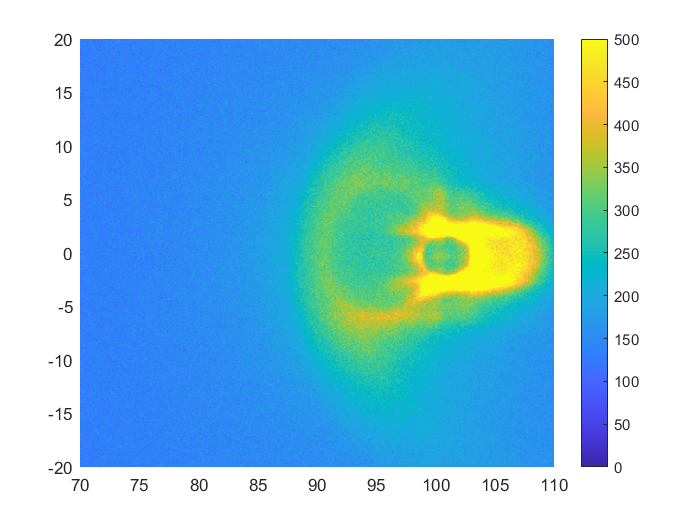

figure;
surf(data2.AZM,data2.THETA,poissrnd(data2.COUNT1'.*300),'EdgeColor','none');
view([0,90]);
colorbar;
caxis([0,500]);

## Experimenting with sparse pdf reconstruction using kernel density estimation

Useful discussion here: https://jakevdp.github.io/PythonDataScienceHandbook/05.13-kernel-density-estimation.html

xbin = -5:0.25:+5;
xbinK = -5:0.1:+5;
mu = 1;
sd = 2;
lambda = 5;
pd = makedist("Normal",mu,sd);
pdnoise = makedist("Uniform",-5,+5);

nSamples = 15;


yHist=zeros(100,length(xbin));
yKern=zeros(100,length(xbinK));
for i = 1:1000
    X = [random(pd,1,nSamples),random(pdnoise,1,30)];
    yHist(i,:) = histcounts(X,[xbin,2*xbin(end)-xbin(end-1)],'Normalization','count');
    yKern(i,:) = ksdensity(X,xbinK,'Kernel',"normal",'Bandwidth',1);
end

[~,iHist]=max(yHist');
peakHist = xbin(iHist);

[~,iKern]=max(yKern');
peakKern = xbinK(iKern);
peakHistRMSE = sqrt(mean((peakHist-mu).^2));
peakKernRMSE = sqrt(mean((peakKern-mu).^2));

disp(['Histogram Peak estimation RMSE = ',num2str(peakHistRMSE,2)])

Histogram Peak estimation RMSE = 2.6


disp(['Kernal Peak estimation RMSE = ',num2str(peakKernRMSE,2)])

Kernal Peak estimation RMSE = 1.3


disp(['Improvement with Kernal Peak Estimation = ',num2str(100.*(peakHistRMSE-peakKernRMSE)./peakHistRMSE,3),'%'])

Improvement with Kernal Peak Estimation = 49.3%


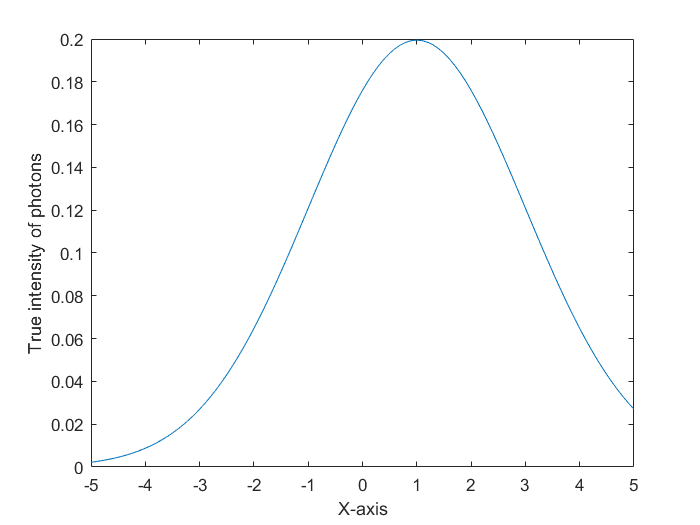


figure;
plot(xbinK,pdf(pd,xbinK));
xlabel('X-axis');
ylabel('True intensity of photons');

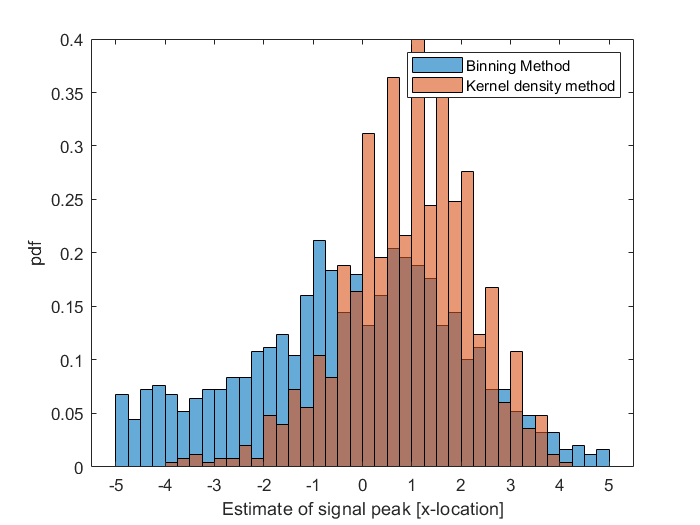


figure;
histogram(peakHist,xbin,'Normalization','pdf');
hold on;
histogram(peakKern,xbin,'Normalization',"pdf");
legend('Binning Method','Kernel density method');
xlabel('Estimate of signal peak [x-location]');
ylabel('pdf');

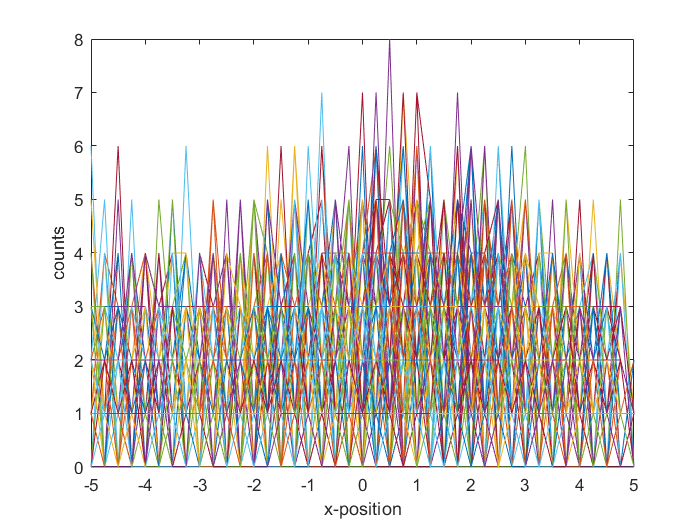


figure;
plot(xbin,yHist);
xlabel('x-position');
ylabel('counts');

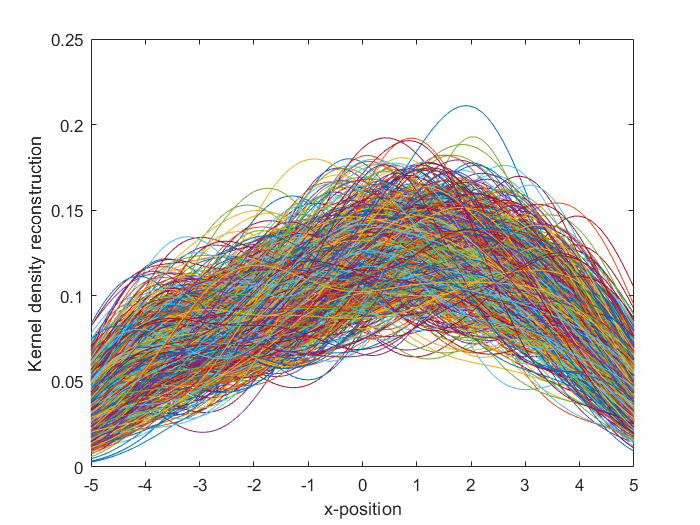


figure;
plot(xbinK,yKern);
xlabel('x-position');
ylabel('Kernel density reconstruction');

## Estimating how bias and variance vary with sample size, bin size and noise

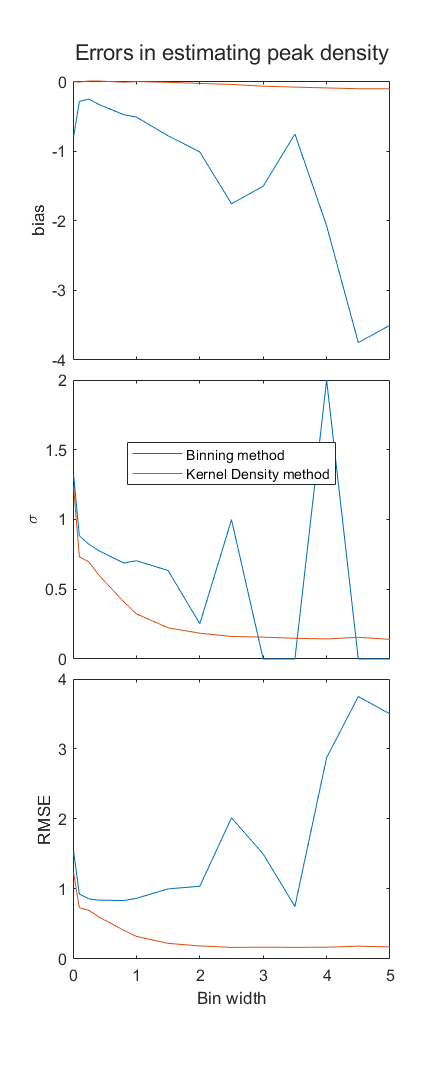

mu = 1;
sd = 2;
pd = makedist("Normal",mu,sd);
pdnoise = makedist("Uniform",-5,+5);

binWidth=[0.01,0.1,0.25,0.4,0.8,1,1.5,2,2.5,3,3.5,4,4.5,5];
    peakHistBias = zeros(1,length(binWidth));
    peakKernBias = zeros(1,length(binWidth));
    
    peakHistStd = zeros(1,length(binWidth));
    peakKernStd = zeros(1,length(binWidth));
    
    peakHistRMSE = zeros(1,length(binWidth));
    peakKernRMSE = zeros(1,length(binWidth));
    
for iBin = 1:length(binWidth)
    xbin = -5:binWidth(iBin):+5;
    xbinH = [xbin-0.5.*binWidth(iBin),xbin(end)+0.5.*binWidth(iBin)];
    xbinK = -5:0.1:+5;
    nSamples = 200;
    nNoiseSamples = 30;

    yHist=zeros(100,length(xbin));
    yKern=zeros(100,length(xbinK));
    
    for i = 1:1000
        X = [random(pd,1,nSamples),random(pdnoise,1,nNoiseSamples)];
        yHist(i,:) = histcounts(X,xbinH,'Normalization','count');
        yKern(i,:) = ksdensity(X,xbinK,'Kernel',"normal",'Bandwidth',binWidth(iBin));
    end
    
    [~,iHist]=max(yHist');
    peakHist = xbinH(iHist);
    
    [~,iKern]=max(yKern');
    peakKern = xbinK(iKern);
    
    peakHistBias(iBin) = mean(peakHist)-mu;
    peakKernBias(iBin) = mean(peakKern)-mu;
    
    peakHistStd(iBin) = std(peakHist);
    peakKernStd(iBin) = std(peakKern);
    
    peakHistRMSE(iBin) = sqrt(mean((peakHist-mu).^2));
    peakKernRMSE(iBin) = sqrt(mean((peakKern-mu).^2));
end

f1=figure; 
resize_figure(f1,300,120);
t=tiledlayout(3,1,'TileSpacing',"tight");

title(t,'Errors in estimating peak density');

nexttile
plot(binWidth,peakHistBias);
hold on;
plot(binWidth,peakKernBias);
set(gca,'XTickLabel',[]);
ylabel('bias');

nexttile
plot(binWidth,peakHistStd);
hold on;
plot(binWidth,peakKernStd);
set(gca,'XTickLabel',[]);
ylabel('\sigma');
legend('Binning method','Kernel Density method','Location','best');

nexttile
plot(binWidth,peakHistRMSE);
hold on;
plot(binWidth,peakKernRMSE);
xlabel('Bin width');
ylabel('RMSE');

## External Functions

function outargs=restore_idl(varargin)
% RESTORE_IDL:  restores variable from an IDL save file into Matlab
% variables.
%
% Input arguments (can appear in any order, and all are optional):
%
%   - filename: complete path specification for the save file
%   - 'lowercase': convert variable names from ALL CAPS to all lowercase
%   - 'verbose': print out analysis of file structure
%   - 'restore_verbose': print out lots of stuff while restoring variables
%   - 'debug': both verbose and restore_verbose
%   - 'split': use the array form of output rather than single structure.
%   - 'create': create Matlab variables instead of returning output
%
% This version restores every variable it knows how to do, and puts them
% all into the output argument array or a struct whose field names are the
% IDL variable names, and field values are the IDL variables themselves.
% The latter (single structure) method is the default.
% 
% To create a MATLAB variable from one of the fields in the single 
% structure, do this:
%   fields=fieldnames(outargs);
%   eval([fields{n} '=outargs.' fields{n} ';']);
%
% optionally output can be a struct array with fields "name" and "value", where
% "name" is the name of the variable, and "value" is a cell array
% containing the variable, whatever it may be.  Could be a scalar, numeric
% array, string, struct, array of structs, nested structs, what have you.
% This option is invoked if  the string "split" is one of the input arguments.
%
% Variables appear in the save file with names in all uppercase, which is
% usually not the convention in matlab, and also regardless of whether the
% user used lower or mixed case in the IDL session that created them.  So
% there is an option here to convert names to all lowercase.  
% 
%
% Original version:
% C. Pelizzari, Oct 2013
%
% (c) 2013, 2015: University of Chicago Image Computing, Analysis and Repository
% Core Facility
%
%
% Sept 2015 - update will corrections made to restore_idl_gui in response
% to user feedback, repackage as callable function vs GUI application.
%
%   April 2018:  add code to handle structure flags PREFEF, INHERITS, 
%                IS_SUPER.  Also print out occasional messages when
%                restoring huge arrays of structs, even when not in verbose
%                mode.  Reassures user something is happening...
%
%                Also add processing for handling heap variables, which
%                have an index rather than a name, and are referred to in
%                other variables by that index.  If a named variable
%                contains a pointer to a heap variable (refers to it by
%                index), the heap variable will be substituted for the
%                pointer value if the corresponding heap variable has been
%                read.  If the corresponding heap variable has not been
%                read, the named variable will contain the pointer value
%                (the heap variable's index) instead.  Since this version
%                of the program restores all variables in the file
%                including the heap variables, this should be transparent
%                to the user.
%
global frestore_verbose thevar verbose h
frestore_verbose=0;
global defined_structures heap_variables heap_indices
defined_structures = {};
heap_variables={};
heap_indices=[];
verbose=0;
h=[];
dolower=0;
split=0;
create=0;
% variables is a struct array that contains info about each variable found
variables=[];
filename=[];
if nargin > 0,
    for i=1:nargin
        if ischar(varargin{i}),
            mystring=varargin{i};
            fp=fopen(mystring);
            if fp > 0,
                filename=mystring;
                fclose(fp);
            else
                if strcmp(lower(mystring),'verbose'),
                    verbose=1;
                end
                if strcmp(lower(mystring),'restore_verbose'),
                    frestore_verbose=1;
                end
                if strcmp(lower(mystring),'lowercase'),
                    dolower=1;
                end
                if strcmp(lower(mystring),'debug'),
                    frestore_verbose=1;
                    verbose=1;
                end
                if strcmp(lower(mystring),'split'),
                    split=1;
                end
                if strcmp(lower(mystring),'create'),
                    create=1;
                end                
            end
        end
    end
end
if isempty(filename),
    [fname,pathname]=uigetfile('*.*','Select IDL save file to restore');
    filename=fullfile(pathname,fname);
end
disp(filename);
fid=fopen(filename);
signature=char(fread(fid,2,'char')');
if verbose, disp(['SIGNATURE = ' signature]), end
alldone=0;
 % convert all variable names to lowercase
if ~strcmp(signature,'SR'),
    disp(['unrecognized signature - terminating.']);
    alldone=1;
end
if ~alldone,
    
recfmts={'COMMON_VARIABLE' 'VARIABLE' 'SYSTEM_VARIABLE' '' '' 'END_MARKER' ...
'' '' '' 'TIMESTAMP' '' 'COMPILED' 'IDENTIFICATION' 'VERSION' ...
'HEAP_HEADER' 'HEAP_DATA' 'PROMOTE64' '' 'NOTICE'};
if verbose, 
    disp('----- Analysis of file structure: -----');
    %fseek(fid,4,'bof');
    nextptr=4;
    while(1)
        fseek(fid,nextptr,'bof');
        recfmt=fread(fid,1,'uint32',0,'b');
        fprintf(1,'Offset %d: record type %s\n', nextptr,recfmts{recfmt});
        if recfmt==6, break, end
        nextptr=fread(fid,1,'uint32',0,'b');
    end
    disp('----------');
end
varnames={};
nextptr=4;
while (1)
 fseek(fid,nextptr,'bof');
    thisptr=nextptr;
    rhdr=fread(fid,1,'uint32',0,'b');
    if feof(fid), break; end % bail out if hit EOF
    nextptr=fread(fid,1,'uint32',0,'b');
    nextptr1=fread(fid,1,'uint32',0,'b');
    unknown=fread(fid,1,'uint32');
    
    % specific format of each type of record is documented in C. Markwardt's
    % description of the file format   
    switch rhdr
        case 10    %timestamp
            if (nextptr < 1024),
                disp('version offset < 1024... probably a compressed file');
                disp('sorry, can''t deal with this.  if possible, save without the "/COMPRESS" flag.')
                return
            end
            unknown=fread(fid,256,'uint32');
            strlen=fread(fid,1,'uint32',0,'b');
            datestring=strtrim(char(fread(fid,4*ceil(strlen/4),'char')'));
            strlen=fread(fid,1,'uint32',0,'b');
            userstring=strtrim(char(fread(fid,4*ceil(strlen/4),'char')'));
            strlen=fread(fid,1,'uint32',0,'b');
            hoststring=strtrim(char(fread(fid,4*ceil(strlen/4),'char')'));
            if verbose,
            disp(['TIMESTAMP:  date, user, host =  ' datestring '  ' userstring '  ' hoststring])
            end
        case 14    % version       
            fmt=fread(fid,1,'uint32',0,'b');
            strlen=fread(fid,1,'uint32',0,'b');
            archstring=strtrim(char(fread(fid,4*ceil(strlen/4),'char')'));
            strlen=fread(fid,1,'uint32',0,'b');
            osstring=strtrim(char(fread(fid,4*ceil(strlen/4),'char')'));
            strlen=fread(fid,1,'uint32',0,'b');
            releasestring=strtrim(char(fread(fid,4*ceil(strlen/4),'char')'));
            if verbose,
            disp(['VERSION: arch, os, release = ' archstring osstring releasestring])
            end
        case 15 %heap header
            if verbose,disp('HEAP HEADER:'); end
            nvalues=fread(fid,1,'int32',0,'b');
            heap_indices=fread(fid,nvalues,'int32',0,'b')';
            if verbose, disp([num2str(nvalues) ' values: ' num2str(heap_indices)]);end
        case 16 % heap data
            if verbose, disp('HEAP DATA:'); end
            heap_index=fread(fid,1,'int32',0,'b');
            whichvar=find(heap_indices==heap_index);
            varname=sprintf('HEAP_%d',heap_index);
            variables(end+1).name=varname;
            variables(end).ptr=thisptr;
            junk=fread(fid,1,'int32',0,'b');
            typecode=fread(fid,1,'int32',0,'b');
            varflags=fread(fid,1,'uint32',0,'b');
            switch typecode
                case 1
                    mytype='uint8';
                case 2
                    mytype='int16';
                case 3
                    mytype='int32';
                case 4
                    mytype='single';
                case 5
                    mytype='double';
                case 6
                    mytype='complex';
                case 7
                    mytype='string';
                case 8
                    mytype='structure';
                case 9
                    mytype='double complex';
                case 10
                    mytype='uint32';
                case 11
                    mytype='object pointer';
                case 12
                    mytype='uint16';
                case 13
                    mytype='uint32';
                case 14
                    mytype='int64';
                case 15
                    mytype='uint64';
            end
            varstring=[ varname ':  '  mytype];
            if ~bitand(varflags,4),  % scalar
                %disp('    SCALAR ');
                varstring=[varstring ' SCALAR'];
            elseif bitand(varflags, 4)  % array   
                arrdesc = parse_array_descriptor(fid);
                dims=arrdesc.dims;
                ndims=arrdesc.ndims;
%                 arrstart=fread(fid,1,'uint32',0,'b');
%                 nbytes_el=fread(fid,1,'uint32',0,'b');
%                 nbytes=fread(fid,1,'uint32',0,'b');
%                 nelements=fread(fid,1,'uint32',0,'b');
%                 ndims=fread(fid,1,'uint32',0,'b');
%                 stuff=fread(fid,2,'uint32',0,'b');
%                 nmax=fread(fid,1,'uint32',0,'b');
%                 dims=fread(fid,nmax,'uint32',0,'b')';
                varstring=[varstring '  ARRAY: '  num2str(dims(1:max([2 ndims])))];
            end
            if verbose, disp(varstring); end
            varnames{end+1}=varstring;
        case 19
            if verbose, disp('NOTICE:'); end
            strlen=fread(fid,1,'uint32',0,'b');
            notestring=strtrim(char(fread(fid,4*ceil(strlen/4),'char')'));
        case 2  % this is the most important one - actual data
            varstring='';
            % here's the name - length first, then the string
            strlen=fread(fid,1,'uint32',0,'b');
            varname=deblank(char(fread(fid,4*ceil(strlen/4),'char')'));
            variables(end+1).name=varname;
            variables(end).ptr=thisptr;
            % typecode tells type of each element in variable
            typecode=fread(fid,1,'uint32',0,'b');
            % varflags tells if it's an array or scalar
            varflags=fread(fid,1,'uint32',0,'b');
            switch typecode
                case 1
                    mytype='uint8';
                case 2
                    mytype='int16';
                case 3
                    mytype='int32';
                case 4
                    mytype='single';
                case 5
                    mytype='double';
                case 6
                    mytype='complex';
                case 7
                    mytype='string';
                case 8
                    mytype='structure';
                case 9
                    mytype='double complex';
                case 10
                    mytype='uint32';
                case 11
                    mytype='object pointer';
                case 12
                    mytype='uint16';
                case 13
                    mytype='uint32';
                case 14
                    mytype='int64';
                case 15
                    mytype='uint64';
            end
            % varstring is our description for the selection listbox
            varstring=[ varname ':  '  mytype];
                   
            if ~bitand(varflags,4),  % scalar
                %disp('    SCALAR ');
                varstring=[varstring ' SCALAR'];
            elseif bitand(varflags, 4)  % array               
                arrstart=fread(fid,1,'uint32',0,'b');
                nbytes_el=fread(fid,1,'uint32',0,'b');
                nbytes=fread(fid,1,'uint32',0,'b');
                nelements=fread(fid,1,'uint32',0,'b');
                ndims=fread(fid,1,'uint32',0,'b');
                stuff=fread(fid,2,'uint32',0,'b');
                nmax=fread(fid,1,'uint32',0,'b');
                dims=fread(fid,nmax,'uint32',0,'b')';
                varstring=[varstring '  ARRAY: ' num2str(dims(1:max([2 ndims])))];
            end
            if verbose, disp(varstring), end
            varnames{end+1}=varstring;
        case 6
            if verbose, disp('END'); end
            break
        otherwise
            
    end
end
%fclose(fid);
end    %if not alldone
choices= 1:numel(variables);
if split,
    outargs=struct('name','','value',{});
else
    if ~create,
        outargs=struct;
    end
end
for whichone=choices,
    if verbose, disp(['Restoring ' variables(whichone).name '...']); end;
    % point to proper place in file
    nextptr=variables(whichone).ptr;
    % go there
    fseek(fid,nextptr,'bof');
    thisptr=nextptr;
    % read the record header
    rhdr=fread(fid,1,'uint32',0,'b');
    %if feof(fid), break; end
    nextptr=fread(fid,1,'uint32',0,'b');
    nextptr1=fread(fid,1,'uint32',0,'b');
    unknown=fread(fid,1,'uint32');
    switch rhdr
       case {2,16} % variable record - read in some data and create a variable
            varstring='';
            switch rhdr
                case 2  % ordinary variable
                    strlen=fread(fid,1,'uint32',0,'b');
                    varname=deblank(char(fread(fid,4*ceil(strlen/4),'char')'));
                case 16 % heap data - index instead of name, extra junk word
                    heap_index=fread(fid,1,'int32',0,'b');
                    varname=sprintf('HEAP_%d',heap_index);
                    junk=fread(fid,1,'int32',0,'b');
            end
            
            % convert to lowercase for Matlab variable naming if desired
            if dolower, varname=lower(varname); end
            
            typecode=fread(fid,1,'uint32',0,'b');
            varflags=fread(fid,1,'uint32',0,'b');
            switch typecode
                case 1
                    mytype='uint8';
                case 2
                    mytype='int16';
                case 3
                    mytype='int32';
                case 4
                    mytype='single';
                case 5
                    mytype='double';
                case 6
                    mytype='complex';
                case 7
                    mytype='string';
                case 8
                    mytype='structure';
                case 9
                    mytype='double complex';
                case 10
                    mytype='uint32';
                case 11
                    mytype='object pointer';
                case 12
                    mytype='uint16';
                case 13
                    mytype='uint32';
                case 14
                    mytype='int64';
                case 15
                    mytype='uint64';
            end
            varstring=[ varname ':  '  mytype];
            if frestore_verbose,disp(varstring),end
            thevar = [];
            if ~bitand(varflags,4),  % scalar
                varstring=[varstring ' SCALAR'];
                thevar=read_idl_scalar(fid,typecode);
                
                if ~isempty(thevar),
                    if frestore_verbose,
                        disp(['creating ' varstring]);
                    end
                    if split,
                        narg=numel(outargs)+1;
                        outargs(narg).name=varname;
                        outargs(narg).value=thevar;
                    else
                        if create,
                            thecommand=['global thevar; ' varname ' = squeeze(thevar);'];
                            evalin('base', thecommand);
                        else
                            outargs.(varname)=thevar;
                        end
                    end
               %     thecommand= ['global thevar; ' varname ' = thevar;'];
               %     evalin('base',thecommand);
                end
            elseif bitand(varflags, 4)  % array (also includes structures)
                if frestore_verbose,disp('doing an array'),end
                thevar=[];
                arrdesc = parse_array_descriptor(fid);
                dims=arrdesc.dims;
                ndims=arrdesc.ndims;
                varstring=[varstring '  ARRAY: ' num2str(dims(1:max([2 ndims])))];
                thevar=read_idl_array(fid,arrdesc,typecode,dolower);
                if ~isempty(thevar),
                    if frestore_verbose,
                        disp(['creating ' varstring]);
                    end
                    thevar= reshape(thevar,dims(1:max([2 ndims])));
                    if split,
                        narg=numel(outargs)+1;
                        outargs(narg).name=varname;
                        outargs(narg).value=thevar;  
                    else
                       if create,
                            thecommand=['global thevar; ' varname ' = squeeze(thevar);'];
                            evalin('base', thecommand);
                        else
                            outargs.(varname)=thevar;
                       end                        
                    end
%                     thecommand=['global thevar; ' varname ' = squeeze(thevar);'];
%                     evalin('base', thecommand);
                end
            end
            if frestore_verbose,
                if numel(thevar) <= 20, thevar, end, 
            end
            if rhdr==16, % save heap variable
                whichvar=find(heap_indices==heap_index);
                heap_variables{whichvar}=thevar;
            end
        otherwise
            % not a variable record, nothing for us to do
    end
end
fclose(fid);
if frestore_verbose && ~isempty(varnames), disp('created new variables '), disp(varnames'),end
end
function mytype = idl_element_type( typecode)
%IDL_ELEMENT_TYPE
%   returns the string descriptor ('float32','int16', etc) given an IDL
%   typecode (a number from 1-15)
    switch typecode
        case 1
            mytype='uint8';
        case 2
            mytype='int16';
        case 3
            mytype='int32';
        case 4
            mytype='single';
        case 5
            mytype='double';
        case 6
            mytype='complex';
        case 7
            mytype='string';
        case 8
            mytype='structure';
        case 9
            mytype='double complex';
        case 10
            mytype='uint32';
        case 11
            mytype='object pointer';
        case 12
            mytype='uint16';
        case 13
            mytype='uint32';
        case 14
            mytype='int64';
        case 15
            mytype='uint64';
    end
end
function strucdesc=new_structure_descriptor()
%NEW_STRUCTURE_DESCRIPTOR - creates a blank structure descriptor record
strucdesc=struct('structstart',0,'name','','predef',0,'ntags',0,...
    'nbytes',0,'tagtable',struct(),'tagnames','','arrtable',[],...
    'structtable',[],'classname','','nsupclasses',0,...
    'supclassnames',0,'supclasstable',[]);
end
function arrdesc = parse_array_descriptor(fid)
    arrdesc=[];
    arrdesc.arrstart=fread(fid,1,'uint32',0,'b');
    arrdesc.nbytes_el=fread(fid,1,'uint32',0,'b');
    arrdesc.nbytes=fread(fid,1,'uint32',0,'b');
    arrdesc.nelements=fread(fid,1,'uint32',0,'b');
    arrdesc.ndims=fread(fid,1,'uint32',0,'b');
    stuff=fread(fid,2,'uint32',0,'b');
    arrdesc.nmax=fread(fid,1,'uint32',0,'b');
    arrdesc.dims=fread(fid,arrdesc.nmax,'uint32',0,'b')';
end
function strucdesc = read_structure_descriptor(fid,varargin)
% READ_STRUCTURE_DESCRIPTOR - get structure descriptor record from IDL save
% file stream
%
% C. Pelizzari, October 2013
%
global defined_structures
strucdesc=new_structure_descriptor; % initialize structure fields
% read start code?  default no
if nargin > 1 && varargin{1},
    strucdesc.structstart=fread(fid,1,'uint32',0,'b');
end
verbose=0;
% first thing is the structure name (not the variable name, but the
% structure type definition name.  we already know the variable name)
strlen=fread(fid,1,'uint32',0,'b');
strucdesc.name=deblank(char(fread(fid,4*ceil(strlen/4),'char')'));
strucdesc.predef=fread(fid,1,'uint32',0,'b'); % predef - we don't handle it
predef=bitand(strucdesc.predef,1);
inherits=bitand(strucdesc.predef,2);
is_super=bitand(strucdesc.predef,4);
strucdesc.ntags=fread(fid,1,'uint32',0,'b'); % ntags - # of fields in struct
nbytes=fread(fid,1,'uint32',0,'b'); % this is not used but have to read it
if predef,
    predef_fail=1;
    if ~isempty(defined_structures),
        matches=cellfun(@(x) strcmp(x.name,strucdesc.name),defined_structures);
        nfound=find(matches);
        if nfound,
            %disp('found structure: copying')
            predef_fail=0;
            strucdesc.tagtable=defined_structures{nfound}.tagtable;
            strucdesc.tagnames=defined_structures{nfound}.tagnames;
            strucdesc.arrtable=defined_structures{nfound}.arrtable;
            strucdesc.structtable=defined_structures{nfound}.structtable;
            strucdesc.classname=defined_structures{nfound}.classname;
            strucdesc.nsupclasses=defined_structures{nfound}.nsupclasses;
            strucdesc.supclassnames=defined_structures{nfound}.supclassnames;
            strucdesc.supclasstable=defined_structures{nfound}.supclasstable;
        end
        
    end
    if predef_fail,
        disp(['STRUCTURE PREDEFINITION FAILURE: ' strucdesc.name ...
            ' NOT FOUND IN PREDEF LIST']);
        return;
    end
       
else
% tagtable has a descriptive entry for each tag (field)
strucdesc.tagtable=struct('offset',[],'typecode',[],'tagflags',[],'name',[]);
for n = 1:strucdesc.ntags
    myoff=fread(fid,1,'uint32',0,'b'); % offset - not used
    mycode=fread(fid,1,'uint32',0,'b'); % type code - what kind of data
    myflags=fread(fid,1,'uint32',0,'b'); % flags - array, structure, etc
    strucdesc.tagtable(n).offset=myoff;
    strucdesc.tagtable(n).typecode=mycode;
    strucdesc.tagtable(n).tagflags=myflags;
end
% next we get all the field names.  put them into the tabtable for
% convenience.  Note we always read a multiple of 4 bytes since the whole
% file structure is organized on 4-byte boundaries.
for n=1:strucdesc.ntags
    strlen=fread(fid,1,'uint32',0,'b');
    strucdesc.tagtable(n).name=...
        deblank(char(fread(fid,4*ceil(strlen/4),'char')'));
end
% see how many arrays and structures there are - will have to process them
myflags=vertcat(strucdesc.tagtable(:).tagflags);
arrflag=hex2dec('04'); % flag for an array
arrmask=bitand(myflags,repmat(arrflag,strucdesc.ntags,1)) > 0;
structflag=hex2dec('20'); % flag for a structure
structmask=bitand(myflags,repmat(structflag,strucdesc.ntags,1)) > 0;
numarrays=numel(find(arrmask));
numstructs=numel(find(structmask));
% read in descriptors for the arrays.  Note that if there are structure
% fields, each of them will also have an array descriptor since structures
% are always contained in arrays, even if they are 1x1.
for n=1:numarrays
       arrdesc =  parse_array_descriptor(fid);
       if n==1, 
           strucdesc.arrtable=arrdesc; 
       else
           strucdesc.arrtable(n)=arrdesc;
       end
end
% read in descriptors for the structures
for n=1:numstructs
       sdesc =  read_structure_descriptor(fid,1);
       if n==1, 
           strucdesc.structtable=sdesc; 
       else
           strucdesc.structtable(n)=sdesc;
       end
end
if is_super || inherits,% read in classdef info
    strlen=fread(fid,1,'uint32',0,'b');
    strucdesc.classname=...
        deblank(char(fread(fid,4*ceil(strlen/4),'char')'));
    strucdesc.nsupclasses=fread(fid,1,'uint32',0,'b');
end
    
    
% if verbose
%     strucdesc
%     for n=1:numarrays
%         strucdesc.arrtable(n)
%     end
% end
defined_structures{end+1}=strucdesc;
end %if predef
end
function thevar = read_idl_structure_new( fid, strucdesc,varargin )
%READ_IDL_STRUCTURE_NEW - read IDL structure data from open file, based on
% information in structure descriptor.
%
% C. Pelizzari Oct 2013
global frestore_verbose verbose
% structure data is preceded by the startcode, a 32-bit integer "7".
if nargin>2 && varargin{1}, 
    startcode=fread(fid,1,'uint32',0,'b');
end
% do we need to convert all tagnames to lower case? default no
dolower=0;
if nargin > 3, dolower=varargin{2}; end
if nargin > 4, nelements=varargin{3};end
if frestore_verbose, 
    disp(['read_idl_structure_new: nelements= ' num2str(nelements) ' at ' num2str(ftell(fid))]);
end
% our output structure
thevar=cell(nelements,1);
%thevar=struct;
ntags=numel(strucdesc.tagtable);  % number of fields (tags)
myflags=vertcat(strucdesc.tagtable(:).tagflags); % flags - array, structure
% find out if there are any tags which are arrays or structures
arrflag=hex2dec('04');  % this marks an array
structflag=hex2dec('20'); % this marks a structure, which will probably 
                            % also be marked as an array
arrmask=bitand(myflags,repmat(arrflag,strucdesc.ntags,1)) > 0;
numarrays=numel(find(arrmask));
structmask=bitand(myflags,repmat(structflag,strucdesc.ntags,1)) > 0;
numstructs=numel(find(structmask));
readstart=0;
printstride=1;
if nelements>10, printstride=10; end
if nelements>100, printstride=100; end
if nelements>1000, printstride=1000; end
if nelements>10000, printstride=5000; end
h=[];
if nelements > 1000, h=waitbar(0, sprintf('Reading structure %d of %d', 1, nelements)); end
for nel=1:nelements
    if verbose && nelements > 1, 
        if  (mod(nel,printstride) == 1), 
            if ishandle(h), waitbar(nel/nelements, h, sprintf('Reading structure %d of %d', nel, nelements)); 
            else disp(['reading structure ' num2str(nel) ' of ' num2str(nelements)]);
            end
        end
    end
    narr=0; % which of the arrays in our table are we processing
    nst=0;
    thevar{nel}=struct;
    for n=1:ntags
        if structmask(n),
            nst=nst+1;
            % skip the array table entry corresponding to this -
            % structures also get flagged as arrays, which we will ignore
            if arrmask(n),
                narr=narr+1;
            end
            % nested structures don't have a startcode, just read the data
            if frestore_verbose,
                disp(['tag number ' num2str(n) ':going to read structure, nelements= ' num2str(strucdesc.arrtable(narr).nelements) ...
                ' at offset ' num2str(ftell(fid))]);
            end
            thisfield=read_idl_structure_new(fid,strucdesc.structtable(nst),0,dolower,strucdesc.arrtable(narr).nelements);
            %thisfield=read_idl_array(fid,strucdesc.arrtable(narr),...
                %strucdesc.tagtable(n).typecode,dolower,readstart,strucdesc);
        elseif arrmask(n),
            narr=narr+1;
            if frestore_verbose, 
            disp(['tag number ' num2str(n) ':going to read array of ' idl_element_type(strucdesc.tagtable(n).typecode) ...
                ' at offset ' num2str(ftell(fid))])
            end
            thisfield=read_idl_array(fid,strucdesc.arrtable(narr),...
                strucdesc.tagtable(n).typecode,dolower,readstart);
        else
            if frestore_verbose,
            disp(['tag number ' num2str(n) ':going to read scalar ' idl_element_type(strucdesc.tagtable(n).typecode) ...
                ' at offset ' num2str(ftell(fid))])
            end
            thisfield=read_idl_scalar(fid,strucdesc.tagtable(n).typecode,0);
        end
        % put data into the appropriate field in our output structure
        name=strucdesc.tagtable(n).name;
        if dolower, name=lower(name);end
        thevar{nel}.(name)=thisfield;
    end
    readstart=0;
    %pause
end
if nelements==1, thevar=thevar{1}; end % no need for cell if only one struct
end
function [ thevar ] = read_idl_array( fid,arrdesc,typecode,varargin )
%READ_IDL_ARRAY - read in array from save file input stream based on array
% descriptor
%
% C. Pelizzari October 2013
global frestore_verbose verbose heap_indices heap_variables
    % convert name to lowercase? default no
    if frestore_verbose,
    disp(['reading array, typecode= ' num2str(typecode)])
    end
     dolower=0;
     if nargin > 3, dolower=varargin{1}; end
     readstart=1;
     if nargin > 4, readstart=varargin{2}; end
     strucdesc=[];
     if nargin > 5, strucdesc=varargin{3}; end
     
     mytype=idl_element_type(typecode); % what kind of data is it
     nelements=arrdesc.nelements; % how many of them
     ndims=arrdesc.ndims; % dimensionality of the array
     dims=arrdesc.dims; % vector of array dimensions
     if frestore_verbose, 
     disp([num2str(nelements) ' ' mytype  ' ' num2str(ndims) ' ' num2str(dims)])
     end
     if (typecode==7)
         thevar = {}; % array of strings may not all be same size - use cell
     elseif (typecode==8)
         thevar=cell(nelements,1); % easiest to use cell for structs too
                                              % since matlab is not very
                                              % smart about arrays of
                                              % structs, e.g. only 1D
     else thevar=[]; 
     end % our output array
     if readstart,startcode=fread(fid,1,'uint32',0,'b'); end % skip the startcode
     switch typecode
        case 1
            lenagain=fread(fid,1,'uint32',0,'b');
            thevar=cast(fread(fid,lenagain,'uint8',0,'b'),mytype);
            leftover=4*ceil(lenagain/4)-lenagain;
            if leftover, fseek(fid,leftover,0); end % move to word boundary
        case {2, 3}
            instuff=fread(fid,nelements,'int32',0,'b');
            thevar=cast(instuff,mytype);
        case 4
            thevar=cast(fread(fid,nelements,'float32',0,'b'),mytype);    
        case 5
            thevar=cast(fread(fid,nelements,'float64',0,'b'),mytype);
        case 6
            thevar=fread(fid,2*nelements,'float32',0,'b');
            thevar=reshape(thevar,2,nelements);
            thevar=complex(thevar(1,:),thevar(2,:));
        case 7  % string
            for thiselement = 1:nelements
            strlng=fread(fid,1,'uint32',0,'b');
                if ~strlng,
                    thevar{thiselement}=''; % zero length string has no further info
                else
                    strlng=fread(fid,1,'uint32',0,'b'); %length again
                    thevar{thiselement}=strtrim(char(fread(fid,4*ceil(strlng/4),'char')'));
                end
            end
        case 8  % structure - next thing in the file is the descriptor
             
             if isempty(strucdesc), strucdesc = read_structure_descriptor(fid,0); end
             if frestore_verbose,
                 disp('strucdesc.tagtable:')
                for ntag=1:numel(strucdesc.tagtable)
                     disp([strucdesc.tagtable(ntag).name ' ' ...
                         num2str(strucdesc.tagtable(ntag).typecode) ' ' ...
                     num2str(strucdesc.tagtable(ntag).offset) ' '])
                 %idl_element_type(strucdesc.tagtable(ntag).typecode) ' ' ...
                end
                disp('strucdesc.arrtable:')
                for narr=1:numel(strucdesc.arrtable)
                 disp([num2str(strucdesc.arrtable(narr).arrstart) ' '...
                     num2str(strucdesc.arrtable(narr).nbytes_el) ' ' ...
                     num2str(strucdesc.arrtable(narr).nbytes) ' ' ...
                     num2str(strucdesc.arrtable(narr).nelements) ' ' ...
                     num2str(strucdesc.arrtable(narr).ndims) ' ' ...
                     num2str(strucdesc.arrtable(narr).nmax) ' ' ...
                     num2str(strucdesc.arrtable(narr).dims)])
                end
                disp('strucdesc.structable:')
                 strucdesc.structtable
                 numel(strucdesc.structtable)
                 for nstruct=1:numel(strucdesc.structtable)
                      disp(['strucdesc.structtable(' num2str(nstruct) '):'])
                     strucdescn=strucdesc.structtable(nstruct)
                      disp(['strucdesc.structtable(' num2str(nstruct) ').tagtable:'])
                    for ntag=1:numel(strucdescn.tagtable)
                                 disp([strucdescn.tagtable(ntag).name ' ' ...
                                 idl_element_type(strucdescn.tagtable(ntag).typecode) ' ' ...
                                 num2str(strucdescn.tagtable(ntag).offset) ' '])
                    end
                    disp(['strucdesc.structtable(' num2str(nstruct) ').arrtable:'])
                    for narr=1:numel(strucdescn.arrtable)
                                 disp([num2str(strucdescn.arrtable(narr).arrstart) ' '...
                                     num2str(strucdescn.arrtable(narr).nbytes_el) ' ' ...
                                     num2str(strucdescn.arrtable(narr).nbytes) ' ' ...
                                     num2str(strucdescn.arrtable(narr).nelements) ' ' ...
                                     num2str(strucdescn.arrtable(narr).ndims) ' ' ...
                                     num2str(strucdescn.arrtable(narr).nmax) ' ' ...
                                     num2str(strucdescn.arrtable(narr).dims)])
                    end
                                 
                 end
             end
             % now read what the descriptor says
             if frestore_verbose,
                 disp(['reading structure array of ' num2str(nelements)])
             end
             thevar=read_idl_structure_new(fid,strucdesc,1,dolower,nelements);
             %  if it's an array of structures, read the rest of them
             %  note that subsequent ones do not have the start code
             %for n=2:nelements
                %thevar{n}=read_idl_structure_norecurse(fid,strucdesc,0,dolower) ; 
             %end
        case 9
            thevar=fread(fid,2*nelements,'float64',0,'b');  
            thevar=reshape(thevar,2,nelements);
            thevar=complex(thevar(1,:),thevar(2,:));
        case {12, 13}
            thevar=cast(fread(fid,nelements,'uint32',0,'b'),mytype);
%             if typecode==10, % see if we have the needed heap variable
%                 whichvar=find(heap_indices==thevar);
%                 if whichvar, thevar=heap_variables{whichvar};end
%             end
        case 14
            thevar=cast(fread(fid,nelements,'int64',0,'b'),mytype);
        case 15
            thevar=cast(fread(fid,nelements,'uint64',0,'b'),mytype);
         otherwise
             return
     end
    thevar=reshape(thevar,dims(1:max([2 ndims])));
    if iscell(thevar) && numel(thevar) == 1,
        thevar = thevar{1};
    end
end
function thevar = read_idl_scalar( fid,typecode,varargin )
% READ_IDL_SCALAR - reads a scalar variable from IDL save file stream
%
% C. Pelizzari, October 2013
%
global heap_indices heap_variables h
    ifstart=1;  % read a start code first? default=yes
    if nargin > 2, ifstart=varargin{1};end % override default
    
    thevar=[];
    mytype=idl_element_type(typecode);  % what kind of variable?
    if ifstart, startcode=fread(fid,1,'uint32',0,'b');end
    switch typecode
        case 1  % byte data
            len=fread(fid,1,'uint32',0,'b');
            thevar=cast(fread(fid,1,'uint8',0,'b'),mytype);
            fseek(fid,3,0); % align on next word boundary
        case {2, 3}  % integers: 16 or 32 bit, saved as 32 bit
            thevar=cast(fread(fid,1,'int32',0,'b'),mytype);
        case 4  % float
            thevar=cast(fread(fid,1,'float32',0,'b'),mytype);
        case 5  % double
            thevar=cast(fread(fid,1,'float64',0,'b'),mytype);
        case 6 % single complex
            thevar=fread(fid,2,'float32',0,'b');
            thevar=complex(thevar(1),thevar(2));
        case 7  % string
             strlng=fread(fid,1,'uint32',0,'b');
             if ~strlng,
                thevar=''; % zero length (null) string has no further info
             else
                strlng=fread(fid,1,'uint32',0,'b');  %another copy of length
                thevar=strtrim(char(fread(fid,4*ceil(strlng/4),'char')'));
             end          
        case 9  % double complex
            thevar=fread(fid,2,'float64',0,'b');
            thevar=complex(thevar(1),thevar(2));
        case {10, 12, 13}  % unsigned ints 16 and 32 bit - saved as 32
            thevar=cast(fread(fid,1,'uint32',0,'b'),mytype);
             if typecode==10, % see if we have the needed heap variable
                whichvar=find(heap_indices==thevar);
                if (numel(heap_variables)>=whichvar) ...
                        && ~isempty(heap_variables{whichvar}), ...
                        thevar=heap_variables{whichvar};
                else  %put up a warning message to restore heap variables.
                    warnstring=...
                        sprintf('Warning!  This variable depends on heap variables.\nYou should restore all the heap variables first!');
                    if ~ishandle(h), h=warndlg(warnstring); end
                end
            end           
        case 14 % long int
            thevar=cast(fread(fid,1,'int64',0,'b'),mytype);
        case 15 % long unsigned int
            thevar=cast(fread(fid,1,'uint64',0,'b'),mytype);                    
        otherwise
    end
end
            